# **Towards stress based topology optimization**

## Simone Coniglio - Joseph Morlier 

In this exercice we will introduce stress based constraint in the classic topology optimization framework of top88.m. You can also use top99.m code, the only difference will be the computational efficiency in Matlab. 

In the first part of this exercice you will be guided to compute Von Mises stress  in the same framework (top88.m). 

We will also treat the efficient implementation of adjoint approach for constraint gradient evaluation of constraint gradient in a Finite Element framework.

 Finally we will use an the most used optimization solver in structural optimization called MMA [3]. The following codes will be provided (mmasub.m, subsolve.m, topstressMMA.m,). Why ? 

Because classical methods (interior point and sequential quadratic programming) already implemented in fmincon Matlab will have a slow convergence rate due to Hessian sparsity. 

## Review of stress evaluation in 2D stress plane quadrilateral elements:

In top88 and top99 we are using structured uniform mesh with constant 1x1 size, in the follow we get the stress for a general square element of side $2a\times2a
$ in the figure below: 

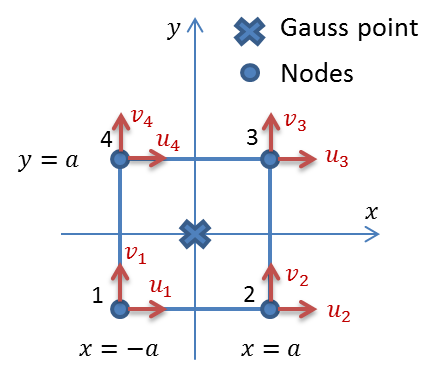

The shape functions $N_i(x,y)$ for $i=1,2,3,4$ are:


$$ N_i(x,y)=\frac{(1+\frac{x_i}{a^2}x)(1+\frac{y_i}{a^2}y)}{4} $$


So that the displacement field can be described as:


$$u(x,y)=\sum_ {i=1}^4N_i(x,y)u_i\\v(x,y)=\sum_ {i=1}^4N_i(x,y)v_i$$


The strain field is simply:

 
$$\epsilon_x(x,y)=\frac{\partial u}{\partial x}(x,y)\\
\epsilon_y(x,y)=\frac{\partial v}{\partial y}(x,y)\\
\gamma_{xy}(x,y)=\frac{\partial v}{\partial x}(x,y)+\frac{\partial u}{\partial v}(x,y)$$


 For clarity we will compute the stress only in a gauss point located in $(0,0)$. In this point the shape function derivatives are:


$$\frac{\partial N_i}{\partial x}(0,0)=\frac{x_i}{4a^2}\\\frac{\partial N_i}{\partial y}(0,0)=\frac{y_i}{4a^2}$$


Then defining the dispacement vector $\lbrace q\rbrace$ as:


$$\lbrace q\rbrace=\left\lbrace u_1,v_1,u_2,v_2,u_3,v_3,u_4,v_4 \right\rbrace^T$$


with $u_1$etc... degrees of freedom depicted in the above picture.

The displacement to strain relationship can be defined as:

 
$$\left\lbrace \begin{array}{c}\epsilon_x\\\epsilon_y\\\gamma_{xy}\end{array}\right\rbrace(0,0)=\frac{1}{4a}\left[\begin{array}{c} -1&0&1&0&1&0&-1&0 \\ 0&-1&0&-1&0&1&0&1 \\-1&-1&-1&1&1&1&1&-1\end{array}\right]\lbrace q\rbrace=[B]\lbrace q\rbrace$$


Once that the strain are linked to displacement the stress vector can also be evauated by the Hooke's generalized law for planar stress defining the stress to strain matrix $[D]$ as:


$$[D]=\frac{E}{1-\nu^2}\left[\begin{array}{ccc}1&\nu&0\\\nu&1&0\\0&0&\frac{1-\nu}{2}\end{array}\right]$$


so that 


$$\left\lbrace \begin{array}{c}\sigma_x\\\sigma_y\\\tau_{xy}\end{array}\right\rbrace(0,0)=[D]\left\lbrace \begin{array}{c}\epsilon_x\\\epsilon_y\\\gamma_{xy}\end{array}\right\rbrace(0,0)=[D][B]\lbrace q \rbrace$$


The Von Mises (VM) stress is the most common criteria used for metallic material failure. Practicaly VM stress value can be seen as the pure normal stress value that is as dangerous as the combined stress state given by the stress tensor. In planar stress it is defined as:


$$\sigma_{VM}=\sqrt{\sigma_x^2+\sigma_y^2-\sigma_x\sigma_y+3\tau_{xy}^2}$$


that can be rewritten in matrix form as:


$$\sigma_{VM}=\sqrt{\left\lbrace\begin{array}{ccc}\sigma_x & \sigma_y&\tau_{xy}\end{array}\right\rbrace\left[\begin{array}{ccc}1& -\frac{1}{2}&0\\-\frac{1}{2} &1 &0\\0&0&3\end{array}\right]\left\lbrace\begin{array}{c}\sigma_x \\ \sigma_y \\ \tau_{xy}\end{array}\right\rbrace}=\sqrt{\lbrace q\rbrace^T [B]^T[D]\left[\begin{array}{ccc}1& -\frac{1}{2}&0\\-\frac{1}{2} &1 &0\\0&0&3\end{array}\right][D][B]\lbrace q\rbrace}=\sqrt{\lbrace q\rbrace^T [S]\lbrace q \rbrace}$$


Since our mesh is uniform $\frac{1}{E}\left[S\right]$ is the same for each element and can be evalued once for all.

## 2a) Verify the stress constraints in final solution of compliance based optimization (solution provided)

Using the formulation above you should be able to evaluate the Von Mises stress in each Element centroid. Modify slightly the 88 line Matlab code of Andreassen including some line for the evaluation of $[S]$ and other for the stress. finally use imagesc matlab function to get the a final stress plot of your design zone.What do you remarck? Which is the final stress distribution? Can you say that your desing is always feasible? 

**Solution (using compare button)**

In our code we made a few changes in the 88lines to fit the new specification see the report of file comparison below:

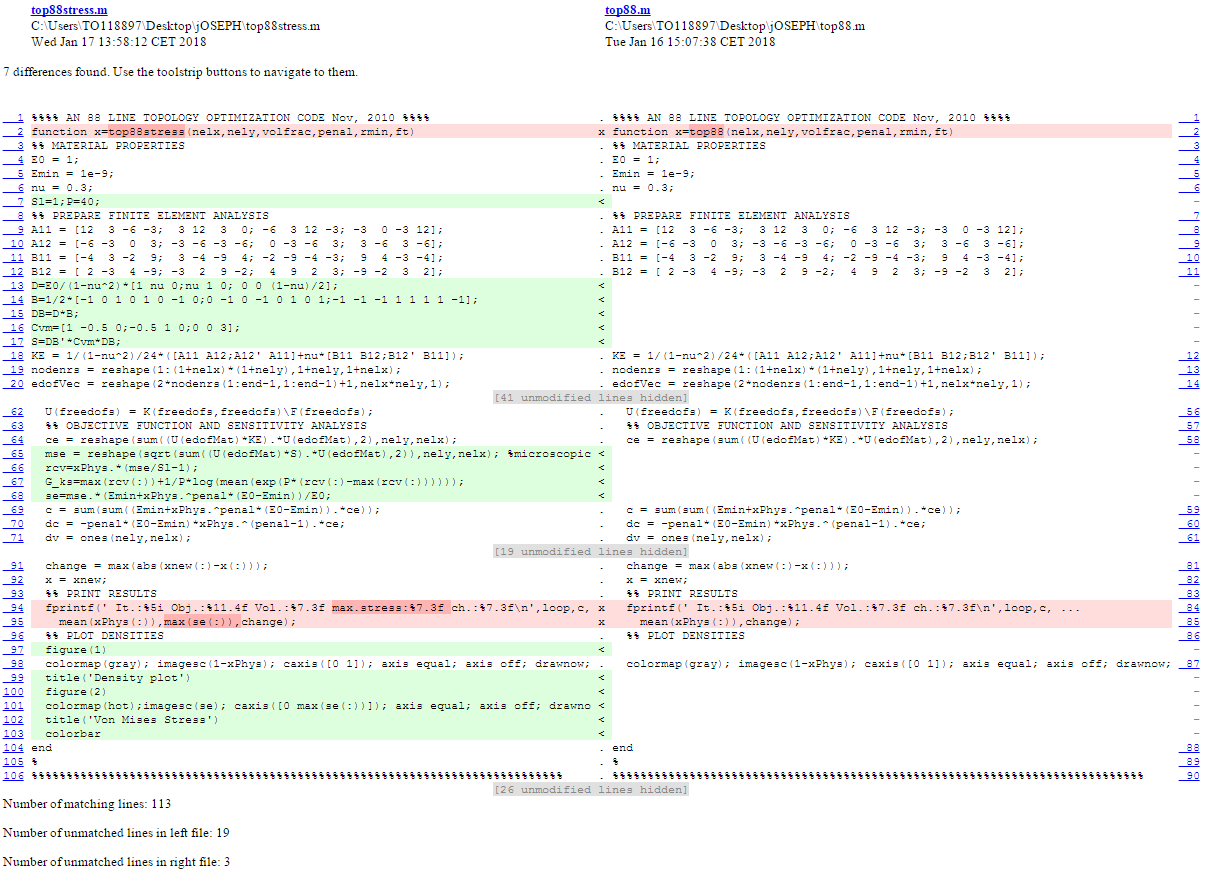

With just these modifications we can get all the answers:

 It.:    1 Obj.: 50746.8755 Vol.:  0.100 max.stress:  1.311 ch.:  0.200
 It.:    2 Obj.: 26377.8651 Vol.:  0.100 max.stress:  1.473 ch.:  0.200
 It.:    3 Obj.: 17870.2300 Vol.:  0.100 max.stress:  3.102 ch.:  0.200
 It.:    4 Obj.: 13978.8536 Vol.:  0.100 max.stress:  3.156 ch.:  0.200
 It.:    5 Obj.: 11435.2674 Vol.:  0.100 max.stress:  4.080 ch.:  0.200
 It.:    6 Obj.:  9485.5018 Vol.:  0.100 max.stress:  3.973 ch.:  0.200
 It.:    7 Obj.:  7982.8915 Vol.:  0.100 max.stress:  4.148 ch.:  0.200
 It.:    8 Obj.:  6723.6532 Vol.:  0.100 max.stress:  3.916 ch.:  0.200
 It.:    9 Obj.:  5706.3844 Vol.:  0.100 max.stress:  4.037 ch.:  0.200
 It.:   10 Obj.:  4959.3920 Vol.:  0.100 max.stress:  3.899 ch.:  0.200
 It.:   11 Obj.:  4261.8122 Vol.:  0.100 max.stress:  4.006 ch.:  0.200
 It.:   12 Obj.:  3730.8679 Vol.:  0.100 max.stress:  3.939 ch.:  0.200
 It.:   13 Obj.:  3185.9652 Vol.:  0.100 max.stress:  4.017 ch.:  0.200
 It.:   14 Obj.:  2703.5096 Vol.:  0.100 max.stress:  3.917 ch.:

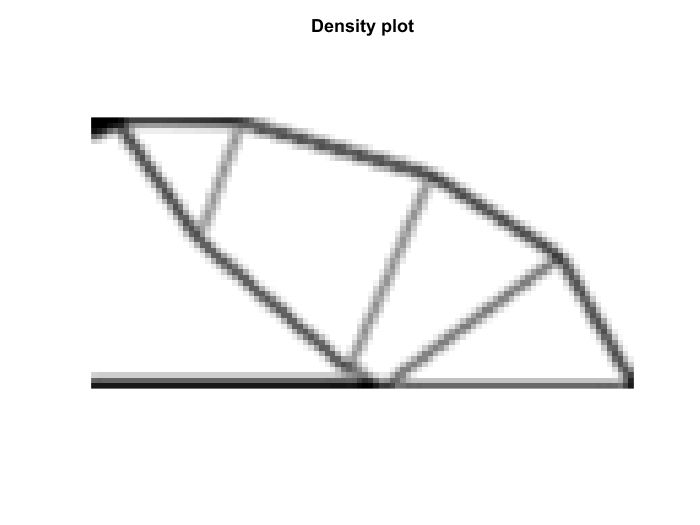

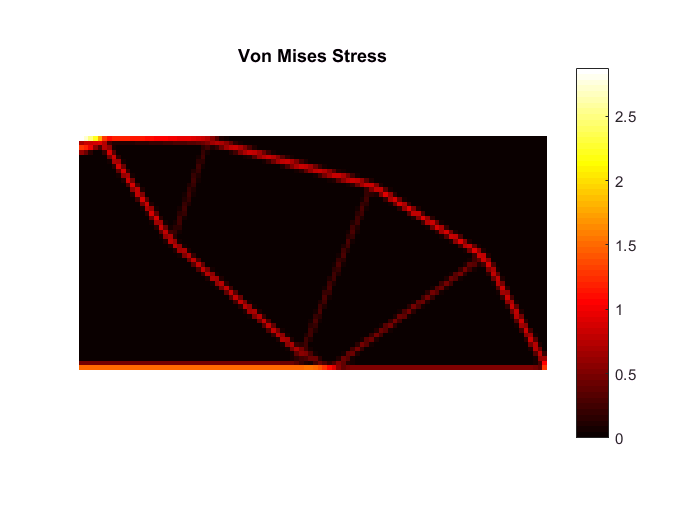

top88stress(100,50,0.1,3,2,2);

Compliance driven topology optimization do not take into account for feasibility constrants. The material could be failing when the volume fraction demanded is too small.

The engineer can't know apriori which level of volume fraction will be feasible. 

In the next we will implement a different approach that avoid this issue.

## 2b) Solving stress based topology optimization problem using fmincon (on the MBB configuration)

Given the design space $\mathbf{D}$ discretized with finite element we want to find the best material layout described by the design variable vector $\lbrace x \rbrace$, that minimize the employed mass  $M(\lbrace x \rbrace ) = \frac{\rho}{N}\sum_{i=1}^Nx_i$ , still respecting stress constraints inside the design zone. For uniforme density the mass is simply proportional to the volume fraction $V(\lbrace x \rbrace ) = \frac{1}{N}\sum_{i=1}^Nx_i$ so that the stress based topology optimization can be formulated as:


$$\left\lbrace\begin{array}{cc}\min_{\lbrace x\rbrace}V(\lbrace x\rbrace)\\
g_i(\lbrace u\left(\lbrace x \rbrace\right) \rbrace)=\frac{\sigma_i(\lbrace u\left(\lbrace x \rbrace\right) \rbrace)}{\sigma_{lim}}-1\leq0 & \forall i\in\lbrace1,2,...,N\rbrace|x_i>0\\
0\leq x_i\leq 1 & \forall i\in\lbrace1,2,...,N\rbrace\\
[K(\lbrace x \rbrace)]\lbrace u\left(\lbrace x \rbrace\right) \rbrace=\lbrace F\rbrace\end{array}\right.$$


The last equation is the static balance of equation deriving from the Finite Element Model of the design zone.

As for the two bar truss problem, this problem shows vanishing constraints. The dumb solution $\lbrace x \rbrace=\lbrace 0 \rbrace$ is eliminated from the design space due to the existance of a displacement solution.

The Young modulus is  obtained by the power low according to [].


$$E_i(x_i)=E_{min}+\left(E_{0}-E_{min} \right)x_i^p \quad p>1$$


To get access to singular optima that are also present in this problem, the unified aggregation and relaxation technique of Verbart [1] is studied here.

Firstly the failure is associated not to the global stress (i.e. the V.M. stress that we obtain using the real young module of the element) but to the microscopic stress (i.e. the V.M. stress per density of material, see [6]). The explaination given to this choice is that an element with an intermediate density can be considered as a composite material layered with full material and voids that have a thickness ratio of $\frac{x}{1-x}$. We get the microscopic stress considering a $[D_0]$ matrix evaluated for full material module $E_0$.

We will note $\sigma_{i0}$ the microscopic stress derived by this definition and as $g_{i0}$ the correspondinc constraint violation. We get the relaxed constraint violation $\bar{g}_{i0}$simply multipling $g_{i0}$ by the corresponding density $x_i$:

The new problem incorporating microscopic stress and relaxation is: 


$$\left\lbrace\begin{array}{cc}\min_{\lbrace x\rbrace}V(\lbrace x\rbrace)\\
\bar{g}_i(\lbrace x \rbrace,\lbrace u\left(\lbrace x \rbrace\right) \rbrace)=x_i\left(\frac{\sigma_{i0}(\lbrace u\left(\lbrace x \rbrace\right) \rbrace)}{\sigma_{lim}}-1\right)\leq0 &\forall i\in\lbrace1,2,...,N\rbrace\\
0\leq x_i\leq 1 & \forall i\in\lbrace1,2,...,N\rbrace\\
[K(\lbrace x \rbrace)]\lbrace u\left(\lbrace x \rbrace\right) \rbrace=\lbrace F\rbrace\end{array}\right.$$


You could try to solve this problem with fmincon getting very slow in each iteration due to the important number of non-linear constraints in your design problem (please try :) ... ). To get faster in this case the aggregation is needed. We will use again the lower bound KS-function to approximate the maximum function.


$$\left\lbrace\begin{array}{cc}\min_{\lbrace x\rbrace}V(\lbrace x\rbrace)\\
G_{KS}(\lbrace x \rbrace,\lbrace u\left(\lbrace x \rbrace\right) \rbrace)=\frac{1}{P}\ln\left(\frac{1}{N}\sum_{i=1}^{N}e^{P\bar{g}_i(\lbrace x \rbrace,\lbrace u\left(\lbrace x \rbrace\right) \rbrace)}\right)\leq0\\
0\leq x_i\leq 1 & \forall i\in\lbrace1,2,...,N\rbrace\\
[K(\lbrace x \rbrace)]\lbrace u\left(\lbrace x \rbrace\right) \rbrace=\lbrace F\rbrace
\end{array}\right.$$


As in the two bar truss problem, you must create two functions: one for the objective and one for the aggregated constraint.

The static balance equation will be embedded in the evaluation of $G_{KS}$ function.

Try to solve the MMB problem with a very small mesh refinement (24*12). Do you find an optimal solution? Can you detect a problem?

**Solution**

Finite difference approach is prohibitive in this case even for a coarse mesh. Objective and constraint gradients must be provided.

##  2c) The adjoint approach for stress gradient sensitivity

The adjoint approach for the evaluation of the constraint is developped in the follows in the general case of response function depending on FEA solution displacement vector $\lbrace u\left(\lbrace x \rbrace\right) \rbrace$.

We want to evaluate the total response sensitivity the vector notation $\lbrace\cdot\rbrace}$ will be neglected for brevity in this paragraph. 


$$\frac{d o(x,u(x))}{dx}=\frac{\partial o(x,u(x))}{\partial x}+\sum_{i=1}^{N_{DOF}}\frac{\partial o(x,u(x))}{\partial u_j}\frac{\partial u_j(x)}{\partial x}$$


Displacement sensitivity are available using derving static balance equation:


$$\frac{d\left([K(\lbrace x \rbrace)]\lbrace u\left(\lbrace x \rbrace\right) \rbrace\right)}{dx}=\frac{d\lbrace F\rbrace}{dx}=\lbrace 0\rbrace$$


So that 


$$\left[\frac{d \lbrace u\rbrace}{d \lbrace x\rbrace}\right]=-[K]^{-1}\left[\bar{\frac{dK}{dx}}\right]\lbrace u \rbrace$$


Where the $\left[\bar{\frac{dK}{dx}}\right]$ is a third order array. The above expression get easier considering one design variable at time.


$$\begin{array}{cccc}\frac{d o(x,u(x))}{dx_i}=\frac{\partial o(x,u(x))}{\partial x_i}-&\left\lbrace\frac{\partial  o(x,u(x))}{\partial u}\right\rbrace^T&[K]^{-1}&\left[\frac{dK}{dx_i}\right]\lbrace u\rbrace\\
& 1\times N_{DOF}& N_{DOF}\times N_{DOF}&N_{DOF}\times 1\end{array}$$


From this equation it is clear that we have a choice, we can either compute one inverse per each design variable computing the therm $[K]^{-1}\left[\frac{dK}{dx_i}\right]\lbrace u\rbrace$ to get the final sensitivity, either compute just once for each response the adjoint vector:


$$\lbrace \lambda\rbrace=[K]^{-1}\left\lbrace\frac{\partial  o(x,u(x))}{\partial u}\right\rbrace$$


and than use this vector to compute all design variable sensitivities as:


$$\frac{d o(x,u(x))}{dx_i}=\frac{\partial o(x,u(x))}{\partial x_i}-\lbrace \lambda\rbrace^T\left[\frac{dK}{dx_i}\right]\lbrace u\rbrace$$


Depending on the size of your problem (i.e. number of responses vs number of variables) the first or the second strategy will be more efficient.

In the case of stress based topology optimization the number of design variable is much greater then the number of response depending on displacement field. Therefore the second approach will be preferred.

get the analytical expression of $\frac{\partial G_{KS}(x,u(x))}{\partial x_i} $ and of $\left\lbrace\frac{\partial G_{KS}(x,u(x))}{\partial u} \right\rbrace$ then compute the total sensitivity by adjoint approach. Provide this gradient to the non-linear constraint function.

**Solution**

It can be showed that


$$\frac{\partial G_{KS}(x,u(x))}{\partial x_j} =\frac{\left(\frac{\sigma_{j0}}{\sigma_{lim}}-1\right)e^{P\bar{g}_j}}{\sum_{i=1}^{N}e^{P\bar{g}_i}}$$



$$\left\lbrace\frac{\partial G_{KS}(x,u(x))}{\partial u} \right\rbrace=\frac{\sum_{i=1}^{N}\frac{x_i}{\sigma_{lim}\sigma_{i0}}e^{P\bar{g}_i}[S_{0i}]\lbrace u\rbrace}{\sum_{i=1}^{N}e^{P\bar{g}_i}}$$


Using the adjoint approach the gradient was provided to fmincon.

As a full hessian matrix is inversed at each optimization step, the computational cost of this approach for topology optimization is still unfeasible!

try also the SQP algorithm. It is even worse!

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    9.900000e-01    0.000e+00    4.136e-03
    1       2    9.808817e-01    0.000e+00    4.136e-03    1.548e-01
    2       3    8.903403e-01    0.000e+00    4.136e-03    1.536e+00
    3       4    8.294019e-01    0.000e+00    4.136e-03    1.034e+00
    4       5    8.186291e-01    1.719e-02    4.136e-03    1.835e-01
    5       6    7.337218e-01    1.385e-01    4.136e-03    1.484e+00
    6       7    7.536219e-01    1.243e-02    4.136e-03    3.860e-01
    7       8    7.373810e-01    1.076e-02    4.136e-03    3.633e-01
    8       9    7.126832e-01    1.341e-02    4.136e-03    5.999e-01
    9      10    7.034956e-01    5.117e-03    4.136e-03    3.504e-01
   10      11    6.957853e-01    2.115e-03    4.136e-03    2.994e-01
   11      12    6.905084e-01    2.527e-04    4.136e-03    2.224e-01
   12      13    6.828815e-01    2.384e-03    4

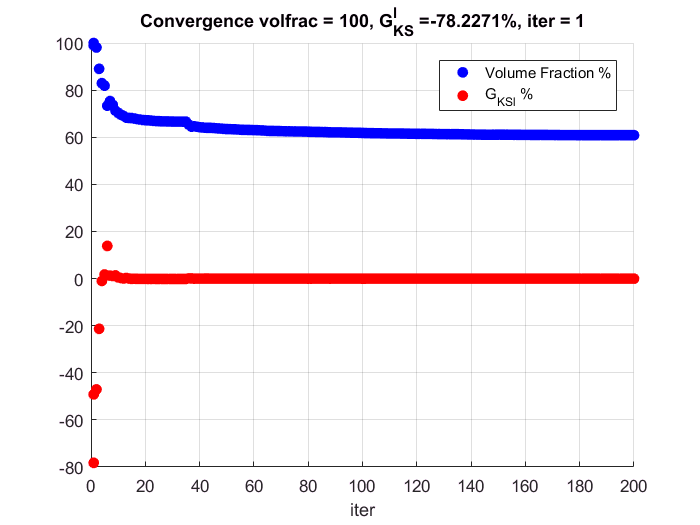

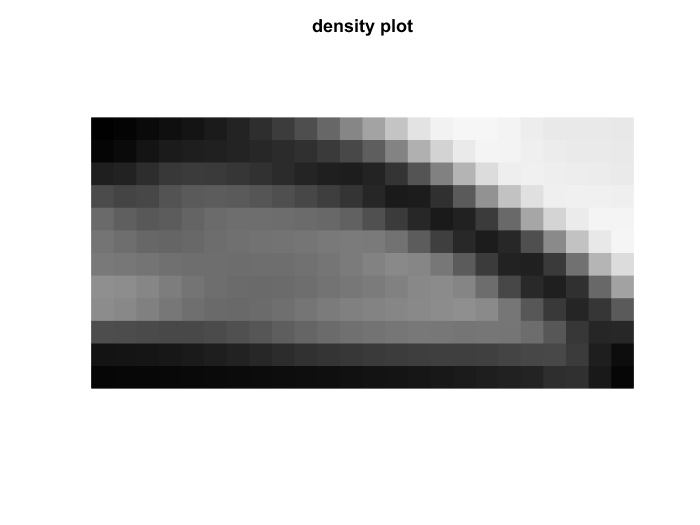

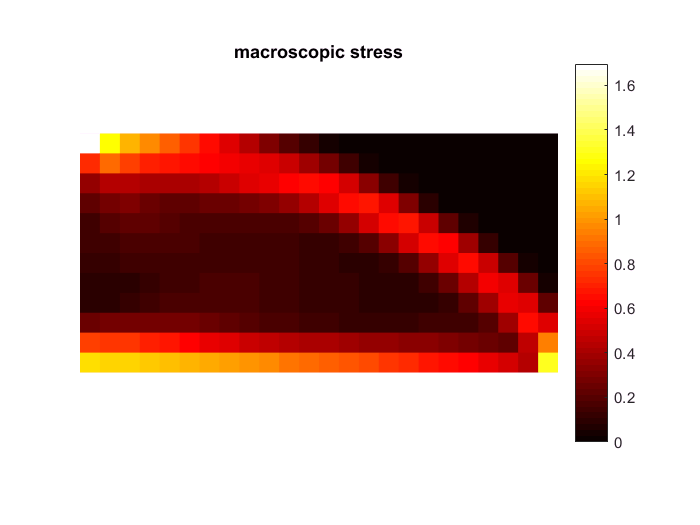

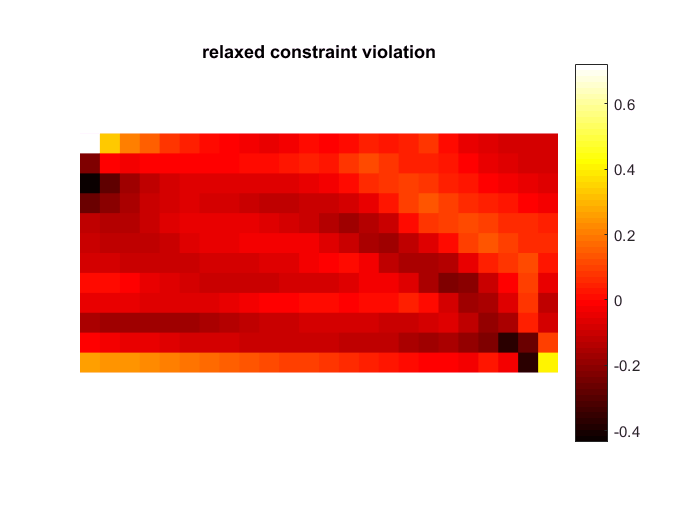

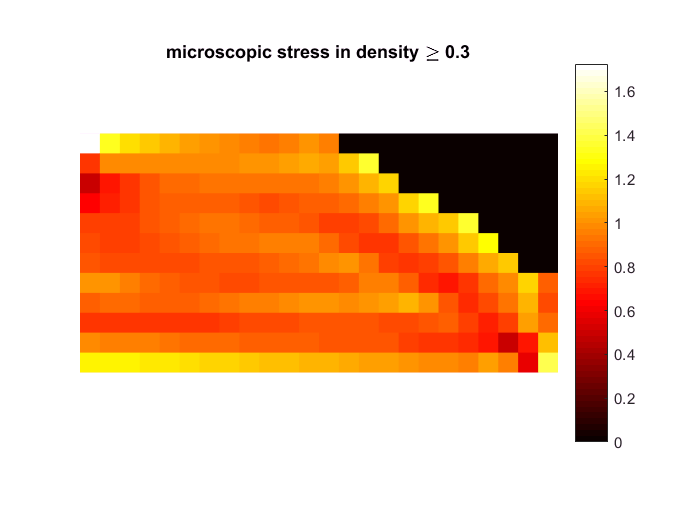

topstress(24,12,3,2,2,1,4);

 Note that the final desing is not even converged and has big grey area that means either that the solver found a local minimum, either that the convergence criteria could not be strong enough.

Looking at the microscopic stress in the element with a density greater than 0.3 one can better understand why the optimization stopped. 

The stress is too big at the boundary condition, the solver stuck in a local minimum.

One should try different mesh refinement in order to get a feasible. Using fmincon this could be prohibitive.

That's why MMA is used in order to get more reasonable mesh refinement in a finite amount of time.

Note that changing the mesh refinement and keeping the rest of the code as it is the design zone change also its geometry. 

##  2d (Bonus)) Try to use MMA optimization solver instead of fmincon

You will be provided of MMA code and documentation of Svanberg. You can use this code only citing his author Svanberg [3].

**solution**

This optimization solver is delicate and can be tuned refering to the reference work of Svanberg and to the provided documentation.

MMA can carry out bigger optimization problem stil keeping fesible design.

The result is this time more understandable.

 It.:    1 Obj.:     1.0000 Const.: -0.782 kktnorm.: 10.002


 It.:    2 Obj.:     0.9210 Const.: -0.629 kktnorm.:  0.642


 It.:    3 Obj.:     0.8422 Const.: -0.446 kktnorm.:  0.629


 It.:    4 Obj.:     0.7643 Const.: -0.307 kktnorm.:  0.446


 It.:    5 Obj.:     0.6897 Const.: -0.218 kktnorm.:  0.308


 It.:    6 Obj.:     0.6275 Const.: -0.121 kktnorm.:  0.219


 It.:    7 Obj.:     0.5822 Const.: -0.052 kktnorm.:  0.124


 It.:    8 Obj.:     0.5541 Const.: -0.019 kktnorm.:  0.056


 It.:    9 Obj.:     0.5387 Const.: -0.008 kktnorm.:  0.027


 It.:   10 Obj.:     0.5288 Const.: -0.006 kktnorm.:  0.020


 It.:   11 Obj.:     0.5214 Const.: -0.004 kktnorm.:  0.016


 It.:   12 Obj.:     0.5156 Const.: -0.003 kktnorm.:  0.014


 It.:   13 Obj.:     0.5109 Const.: -0.003 kktnorm.:  0.013


 It.:   14 Obj.:     0.5069 Const.: -0.002 kktnorm.:  0.011


 It.:   15 Obj.:     0.5034 Const.: -0.002 kktnorm.:  0.010


 It.:   16 Obj.:     0.5003 Const.: -0.002 kktnorm.:  0.010


 It.:   17 Obj.:     0.4973 Const.: -0.002 kktnorm.:  0.009


 It.:   18 Obj.:     0.4945 Const.: -0.002 kktnorm.:  0.009


 It.:   19 Obj.:     0.4916 Const.: -0.002 kktnorm.:  0.009


 It.:   20 Obj.:     0.4889 Const.: -0.002 kktnorm.:  0.008


 It.:   21 Obj.:     0.4864 Const.: -0.001 kktnorm.:  0.008


 It.:   22 Obj.:     0.4841 Const.: -0.001 kktnorm.:  0.008


 It.:   23 Obj.:     0.4819 Const.: -0.001 kktnorm.:  0.007


 It.:   24 Obj.:     0.4798 Const.: -0.001 kktnorm.:  0.007


 It.:   25 Obj.:     0.4779 Const.: -0.001 kktnorm.:  0.007


 It.:   26 Obj.:     0.4760 Const.: -0.001 kktnorm.:  0.007


 It.:   27 Obj.:     0.4742 Const.: -0.001 kktnorm.:  0.006


 It.:   28 Obj.:     0.4725 Const.: -0.001 kktnorm.:  0.006


 It.:   29 Obj.:     0.4709 Const.: -0.001 kktnorm.:  0.006


 It.:   30 Obj.:     0.4694 Const.: -0.001 kktnorm.:  0.006


 It.:   31 Obj.:     0.4680 Const.: -0.001 kktnorm.:  0.006


 It.:   32 Obj.:     0.4666 Const.: -0.001 kktnorm.:  0.006


 It.:   33 Obj.:     0.4653 Const.: -0.001 kktnorm.:  0.006


 It.:   34 Obj.:     0.4640 Const.: -0.001 kktnorm.:  0.006


 It.:   35 Obj.:     0.4627 Const.: -0.001 kktnorm.:  0.005


 It.:   36 Obj.:     0.4615 Const.: -0.001 kktnorm.:  0.005


 It.:   37 Obj.:     0.4604 Const.: -0.001 kktnorm.:  0.005


 It.:   38 Obj.:     0.4593 Const.: -0.001 kktnorm.:  0.005


 It.:   39 Obj.:     0.4582 Const.: -0.001 kktnorm.:  0.005


 It.:   40 Obj.:     0.4571 Const.: -0.001 kktnorm.:  0.005


 It.:   41 Obj.:     0.4561 Const.: -0.001 kktnorm.:  0.005


 It.:   42 Obj.:     0.4552 Const.: -0.001 kktnorm.:  0.005


 It.:   43 Obj.:     0.4543 Const.: -0.001 kktnorm.:  0.005


 It.:   44 Obj.:     0.4533 Const.: -0.001 kktnorm.:  0.005


 It.:   45 Obj.:     0.4523 Const.: -0.001 kktnorm.:  0.005


 It.:   46 Obj.:     0.4513 Const.: -0.001 kktnorm.:  0.005


 It.:   47 Obj.:     0.4499 Const.: -0.001 kktnorm.:  0.005


 It.:   48 Obj.:     0.4483 Const.: -0.001 kktnorm.:  0.005


 It.:   49 Obj.:     0.4469 Const.: -0.001 kktnorm.:  0.005


 It.:   50 Obj.:     0.4457 Const.: -0.001 kktnorm.:  0.005


 It.:   51 Obj.:     0.4445 Const.: -0.001 kktnorm.:  0.005


 It.:   52 Obj.:     0.4434 Const.: -0.001 kktnorm.:  0.005


 It.:   53 Obj.:     0.4422 Const.: -0.001 kktnorm.:  0.005


 It.:   54 Obj.:     0.4412 Const.: -0.001 kktnorm.:  0.005


 It.:   55 Obj.:     0.4402 Const.: -0.001 kktnorm.:  0.005


 It.:   56 Obj.:     0.4391 Const.: -0.001 kktnorm.:  0.005


 It.:   57 Obj.:     0.4381 Const.: -0.001 kktnorm.:  0.005


 It.:   58 Obj.:     0.4370 Const.: -0.001 kktnorm.:  0.005


 It.:   59 Obj.:     0.4361 Const.: -0.000 kktnorm.:  0.004


 It.:   60 Obj.:     0.4353 Const.: -0.000 kktnorm.:  0.004


 It.:   61 Obj.:     0.4345 Const.: -0.000 kktnorm.:  0.004


 It.:   62 Obj.:     0.4337 Const.: -0.000 kktnorm.:  0.004


 It.:   63 Obj.:     0.4328 Const.: -0.000 kktnorm.:  0.004


 It.:   64 Obj.:     0.4320 Const.: -0.000 kktnorm.:  0.004


 It.:   65 Obj.:     0.4311 Const.: -0.000 kktnorm.:  0.004


 It.:   66 Obj.:     0.4302 Const.: -0.000 kktnorm.:  0.004


 It.:   67 Obj.:     0.4295 Const.: -0.000 kktnorm.:  0.004


 It.:   68 Obj.:     0.4288 Const.: -0.000 kktnorm.:  0.004


 It.:   69 Obj.:     0.4281 Const.: -0.000 kktnorm.:  0.004


 It.:   70 Obj.:     0.4274 Const.: -0.000 kktnorm.:  0.004


 It.:   71 Obj.:     0.4267 Const.: -0.000 kktnorm.:  0.004


 It.:   72 Obj.:     0.4259 Const.: -0.000 kktnorm.:  0.004


 It.:   73 Obj.:     0.4252 Const.: -0.000 kktnorm.:  0.004


 It.:   74 Obj.:     0.4245 Const.: -0.000 kktnorm.:  0.004


 It.:   75 Obj.:     0.4238 Const.: -0.000 kktnorm.:  0.004


 It.:   76 Obj.:     0.4231 Const.: -0.000 kktnorm.:  0.004


 It.:   77 Obj.:     0.4225 Const.: -0.000 kktnorm.:  0.004


 It.:   78 Obj.:     0.4218 Const.: -0.000 kktnorm.:  0.004


 It.:   79 Obj.:     0.4212 Const.: -0.000 kktnorm.:  0.004


 It.:   80 Obj.:     0.4207 Const.: -0.000 kktnorm.:  0.004


 It.:   81 Obj.:     0.4201 Const.: -0.000 kktnorm.:  0.004


 It.:   82 Obj.:     0.4196 Const.: -0.000 kktnorm.:  0.004


 It.:   83 Obj.:     0.4191 Const.: -0.000 kktnorm.:  0.004


 It.:   84 Obj.:     0.4185 Const.: -0.000 kktnorm.:  0.004


 It.:   85 Obj.:     0.4179 Const.: -0.000 kktnorm.:  0.004


 It.:   86 Obj.:     0.4174 Const.: -0.000 kktnorm.:  0.004


 It.:   87 Obj.:     0.4169 Const.: -0.000 kktnorm.:  0.004


 It.:   88 Obj.:     0.4163 Const.: -0.000 kktnorm.:  0.004


 It.:   89 Obj.:     0.4158 Const.: -0.000 kktnorm.:  0.004


 It.:   90 Obj.:     0.4153 Const.: -0.000 kktnorm.:  0.004


 It.:   91 Obj.:     0.4147 Const.: -0.000 kktnorm.:  0.004


 It.:   92 Obj.:     0.4142 Const.: -0.000 kktnorm.:  0.004


 It.:   93 Obj.:     0.4136 Const.: -0.000 kktnorm.:  0.004


 It.:   94 Obj.:     0.4130 Const.: -0.000 kktnorm.:  0.004


 It.:   95 Obj.:     0.4125 Const.: -0.000 kktnorm.:  0.004


 It.:   96 Obj.:     0.4120 Const.: -0.000 kktnorm.:  0.004


 It.:   97 Obj.:     0.4115 Const.: -0.000 kktnorm.:  0.004


 It.:   98 Obj.:     0.4110 Const.: -0.000 kktnorm.:  0.003


 It.:   99 Obj.:     0.4105 Const.: -0.000 kktnorm.:  0.003


 It.:  100 Obj.:     0.4101 Const.: -0.000 kktnorm.:  0.003


 It.:  101 Obj.:     0.4096 Const.: -0.000 kktnorm.:  0.003


 It.:  102 Obj.:     0.4091 Const.: -0.000 kktnorm.:  0.003


 It.:  103 Obj.:     0.4087 Const.: -0.000 kktnorm.:  0.003


 It.:  104 Obj.:     0.4082 Const.: -0.000 kktnorm.:  0.003


 It.:  105 Obj.:     0.4077 Const.: -0.000 kktnorm.:  0.003


 It.:  106 Obj.:     0.4072 Const.: -0.000 kktnorm.:  0.003


 It.:  107 Obj.:     0.4068 Const.: -0.000 kktnorm.:  0.003


 It.:  108 Obj.:     0.4063 Const.: -0.000 kktnorm.:  0.003


 It.:  109 Obj.:     0.4059 Const.: -0.000 kktnorm.:  0.003


 It.:  110 Obj.:     0.4055 Const.: -0.000 kktnorm.:  0.003


 It.:  111 Obj.:     0.4051 Const.: -0.000 kktnorm.:  0.003


 It.:  112 Obj.:     0.4046 Const.: -0.000 kktnorm.:  0.003


 It.:  113 Obj.:     0.4042 Const.: -0.000 kktnorm.:  0.003


 It.:  114 Obj.:     0.4037 Const.: -0.000 kktnorm.:  0.003


 It.:  115 Obj.:     0.4032 Const.: -0.000 kktnorm.:  0.003


 It.:  116 Obj.:     0.4027 Const.: -0.000 kktnorm.:  0.004


 It.:  117 Obj.:     0.4023 Const.: -0.000 kktnorm.:  0.004


 It.:  118 Obj.:     0.4018 Const.: -0.000 kktnorm.:  0.004


 It.:  119 Obj.:     0.4013 Const.: -0.000 kktnorm.:  0.004


 It.:  120 Obj.:     0.4008 Const.: -0.000 kktnorm.:  0.004


 It.:  121 Obj.:     0.4002 Const.: -0.000 kktnorm.:  0.004


 It.:  122 Obj.:     0.3997 Const.: -0.000 kktnorm.:  0.004


 It.:  123 Obj.:     0.3991 Const.: -0.000 kktnorm.:  0.004


 It.:  124 Obj.:     0.3986 Const.: -0.000 kktnorm.:  0.004


 It.:  125 Obj.:     0.3980 Const.: -0.000 kktnorm.:  0.004


 It.:  126 Obj.:     0.3974 Const.: -0.000 kktnorm.:  0.004


 It.:  127 Obj.:     0.3968 Const.: -0.000 kktnorm.:  0.004


 It.:  128 Obj.:     0.3961 Const.: -0.000 kktnorm.:  0.004


 It.:  129 Obj.:     0.3954 Const.: -0.000 kktnorm.:  0.004


 It.:  130 Obj.:     0.3946 Const.: -0.000 kktnorm.:  0.005


 It.:  131 Obj.:     0.3936 Const.: -0.001 kktnorm.:  0.005


 It.:  132 Obj.:     0.3924 Const.: -0.001 kktnorm.:  0.005


 It.:  133 Obj.:     0.3905 Const.: -0.001 kktnorm.:  0.006


 It.:  134 Obj.:     0.3869 Const.: -0.003 kktnorm.:  0.008


 It.:  135 Obj.:     0.3831 Const.: -0.001 kktnorm.:  0.007


 It.:  136 Obj.:     0.3811 Const.: -0.001 kktnorm.:  0.006


 It.:  137 Obj.:     0.3796 Const.: -0.001 kktnorm.:  0.005


 It.:  138 Obj.:     0.3781 Const.: -0.001 kktnorm.:  0.005


 It.:  139 Obj.:     0.3766 Const.: -0.001 kktnorm.:  0.005


 It.:  140 Obj.:     0.3751 Const.: -0.001 kktnorm.:  0.005


 It.:  141 Obj.:     0.3735 Const.: -0.001 kktnorm.:  0.006


 It.:  142 Obj.:     0.3718 Const.: -0.001 kktnorm.:  0.006


 It.:  143 Obj.:     0.3701 Const.: -0.001 kktnorm.:  0.006


 It.:  144 Obj.:     0.3684 Const.: -0.001 kktnorm.:  0.006


 It.:  145 Obj.:     0.3667 Const.: -0.001 kktnorm.:  0.006


 It.:  146 Obj.:     0.3651 Const.: -0.001 kktnorm.:  0.006


 It.:  147 Obj.:     0.3635 Const.: -0.001 kktnorm.:  0.005


 It.:  148 Obj.:     0.3619 Const.: -0.001 kktnorm.:  0.006


 It.:  149 Obj.:     0.3604 Const.: -0.001 kktnorm.:  0.006


 It.:  150 Obj.:     0.3588 Const.: -0.001 kktnorm.:  0.005


 It.:  151 Obj.:     0.3574 Const.: -0.001 kktnorm.:  0.005


 It.:  152 Obj.:     0.3561 Const.: -0.001 kktnorm.:  0.005


 It.:  153 Obj.:     0.3547 Const.: -0.001 kktnorm.:  0.005


 It.:  154 Obj.:     0.3533 Const.: -0.001 kktnorm.:  0.005


 It.:  155 Obj.:     0.3521 Const.: -0.001 kktnorm.:  0.005


 It.:  156 Obj.:     0.3507 Const.: -0.001 kktnorm.:  0.005


 It.:  157 Obj.:     0.3494 Const.: -0.001 kktnorm.:  0.005


 It.:  158 Obj.:     0.3483 Const.: -0.001 kktnorm.:  0.005


 It.:  159 Obj.:     0.3470 Const.: -0.001 kktnorm.:  0.005


 It.:  160 Obj.:     0.3458 Const.: -0.001 kktnorm.:  0.005


 It.:  161 Obj.:     0.3446 Const.: -0.000 kktnorm.:  0.005


 It.:  162 Obj.:     0.3435 Const.: -0.000 kktnorm.:  0.005


 It.:  163 Obj.:     0.3424 Const.: -0.001 kktnorm.:  0.005


 It.:  164 Obj.:     0.3411 Const.: -0.001 kktnorm.:  0.005


 It.:  165 Obj.:     0.3399 Const.: -0.001 kktnorm.:  0.005


 It.:  166 Obj.:     0.3387 Const.: -0.001 kktnorm.:  0.005


 It.:  167 Obj.:     0.3375 Const.: -0.001 kktnorm.:  0.005


 It.:  168 Obj.:     0.3362 Const.: -0.001 kktnorm.:  0.005


 It.:  169 Obj.:     0.3347 Const.: -0.001 kktnorm.:  0.005


 It.:  170 Obj.:     0.3327 Const.: -0.001 kktnorm.:  0.006


 It.:  171 Obj.:     0.3310 Const.: -0.001 kktnorm.:  0.005


 It.:  172 Obj.:     0.3299 Const.: -0.000 kktnorm.:  0.005


 It.:  173 Obj.:     0.3290 Const.: -0.000 kktnorm.:  0.004


 It.:  174 Obj.:     0.3282 Const.: -0.000 kktnorm.:  0.004


 It.:  175 Obj.:     0.3274 Const.: -0.000 kktnorm.:  0.004


 It.:  176 Obj.:     0.3266 Const.: -0.000 kktnorm.:  0.004


 It.:  177 Obj.:     0.3259 Const.: -0.000 kktnorm.:  0.004


 It.:  178 Obj.:     0.3253 Const.: -0.000 kktnorm.:  0.004


 It.:  179 Obj.:     0.3247 Const.: -0.000 kktnorm.:  0.004


 It.:  180 Obj.:     0.3241 Const.: -0.000 kktnorm.:  0.004


 It.:  181 Obj.:     0.3235 Const.: -0.000 kktnorm.:  0.004


 It.:  182 Obj.:     0.3229 Const.: -0.000 kktnorm.:  0.004


 It.:  183 Obj.:     0.3223 Const.: -0.000 kktnorm.:  0.004


 It.:  184 Obj.:     0.3218 Const.: -0.000 kktnorm.:  0.004


 It.:  185 Obj.:     0.3212 Const.: -0.000 kktnorm.:  0.004


 It.:  186 Obj.:     0.3207 Const.: -0.000 kktnorm.:  0.003


 It.:  187 Obj.:     0.3203 Const.: -0.000 kktnorm.:  0.003


 It.:  188 Obj.:     0.3198 Const.: -0.000 kktnorm.:  0.003


 It.:  189 Obj.:     0.3194 Const.: -0.000 kktnorm.:  0.003


 It.:  190 Obj.:     0.3190 Const.: -0.000 kktnorm.:  0.003


 It.:  191 Obj.:     0.3186 Const.: -0.000 kktnorm.:  0.003


 It.:  192 Obj.:     0.3182 Const.: -0.000 kktnorm.:  0.003


 It.:  193 Obj.:     0.3178 Const.: -0.000 kktnorm.:  0.003


 It.:  194 Obj.:     0.3174 Const.: -0.000 kktnorm.:  0.003


 It.:  195 Obj.:     0.3170 Const.: -0.000 kktnorm.:  0.003


 It.:  196 Obj.:     0.3166 Const.: -0.000 kktnorm.:  0.003


 It.:  197 Obj.:     0.3162 Const.: -0.000 kktnorm.:  0.003


 It.:  198 Obj.:     0.3158 Const.: -0.000 kktnorm.:  0.003


 It.:  199 Obj.:     0.3153 Const.: -0.000 kktnorm.:  0.003


 It.:  200 Obj.:     0.3149 Const.: -0.000 kktnorm.:  0.003


 It.:  201 Obj.:     0.3145 Const.: -0.000 kktnorm.:  0.003


 It.:  202 Obj.:     0.3142 Const.: -0.000 kktnorm.:  0.003


 It.:  203 Obj.:     0.3138 Const.: -0.000 kktnorm.:  0.003


 It.:  204 Obj.:     0.3135 Const.: -0.000 kktnorm.:  0.003


 It.:  205 Obj.:     0.3132 Const.: -0.000 kktnorm.:  0.003


 It.:  206 Obj.:     0.3128 Const.: -0.000 kktnorm.:  0.003


 It.:  207 Obj.:     0.3125 Const.: -0.000 kktnorm.:  0.003


 It.:  208 Obj.:     0.3122 Const.: -0.000 kktnorm.:  0.003


 It.:  209 Obj.:     0.3119 Const.: -0.000 kktnorm.:  0.003


 It.:  210 Obj.:     0.3116 Const.: -0.000 kktnorm.:  0.003


 It.:  211 Obj.:     0.3113 Const.: -0.000 kktnorm.:  0.003


 It.:  212 Obj.:     0.3110 Const.: -0.000 kktnorm.:  0.003


 It.:  213 Obj.:     0.3107 Const.: -0.000 kktnorm.:  0.003


 It.:  214 Obj.:     0.3104 Const.: -0.000 kktnorm.:  0.003


 It.:  215 Obj.:     0.3102 Const.: -0.000 kktnorm.:  0.003


 It.:  216 Obj.:     0.3099 Const.: -0.000 kktnorm.:  0.003


 It.:  217 Obj.:     0.3096 Const.: -0.000 kktnorm.:  0.003


 It.:  218 Obj.:     0.3093 Const.: -0.000 kktnorm.:  0.003


 It.:  219 Obj.:     0.3091 Const.: -0.000 kktnorm.:  0.003


 It.:  220 Obj.:     0.3088 Const.: -0.000 kktnorm.:  0.003


 It.:  221 Obj.:     0.3085 Const.: -0.000 kktnorm.:  0.003


 It.:  222 Obj.:     0.3083 Const.: -0.000 kktnorm.:  0.002


 It.:  223 Obj.:     0.3081 Const.: -0.000 kktnorm.:  0.002


 It.:  224 Obj.:     0.3079 Const.: -0.000 kktnorm.:  0.002


 It.:  225 Obj.:     0.3077 Const.: -0.000 kktnorm.:  0.002


 It.:  226 Obj.:     0.3075 Const.: -0.000 kktnorm.:  0.002


 It.:  227 Obj.:     0.3073 Const.: -0.000 kktnorm.:  0.002


 It.:  228 Obj.:     0.3071 Const.: -0.000 kktnorm.:  0.002


 It.:  229 Obj.:     0.3069 Const.: -0.000 kktnorm.:  0.002


 It.:  230 Obj.:     0.3067 Const.: -0.000 kktnorm.:  0.002


 It.:  231 Obj.:     0.3066 Const.: -0.000 kktnorm.:  0.002


 It.:  232 Obj.:     0.3064 Const.: -0.000 kktnorm.:  0.002


 It.:  233 Obj.:     0.3062 Const.: -0.000 kktnorm.:  0.002


 It.:  234 Obj.:     0.3060 Const.: -0.000 kktnorm.:  0.002


 It.:  235 Obj.:     0.3059 Const.: -0.000 kktnorm.:  0.002


 It.:  236 Obj.:     0.3057 Const.: -0.000 kktnorm.:  0.002


 It.:  237 Obj.:     0.3055 Const.: -0.000 kktnorm.:  0.002


 It.:  238 Obj.:     0.3054 Const.: -0.000 kktnorm.:  0.002


 It.:  239 Obj.:     0.3052 Const.: -0.000 kktnorm.:  0.002


 It.:  240 Obj.:     0.3050 Const.: -0.000 kktnorm.:  0.002


 It.:  241 Obj.:     0.3048 Const.: -0.000 kktnorm.:  0.002


 It.:  242 Obj.:     0.3046 Const.: -0.000 kktnorm.:  0.002


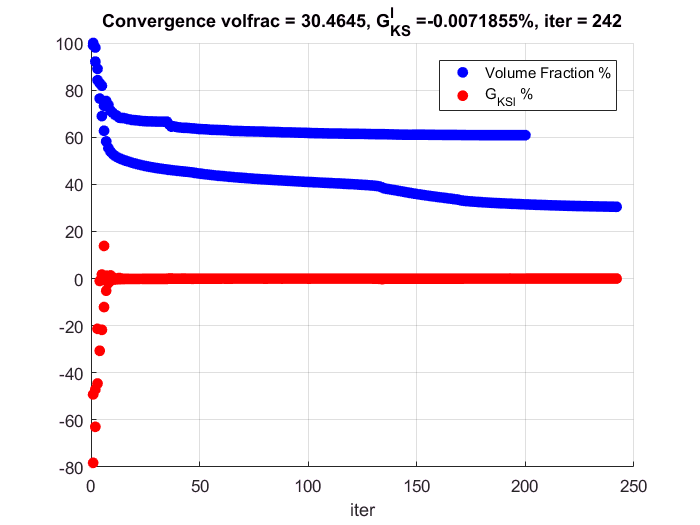

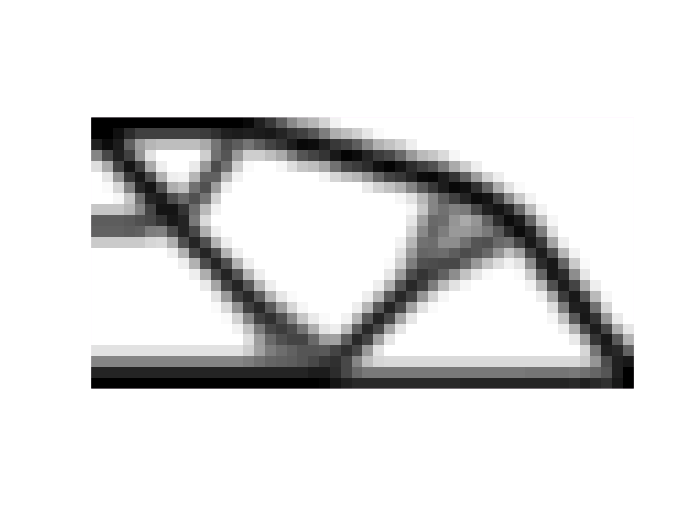

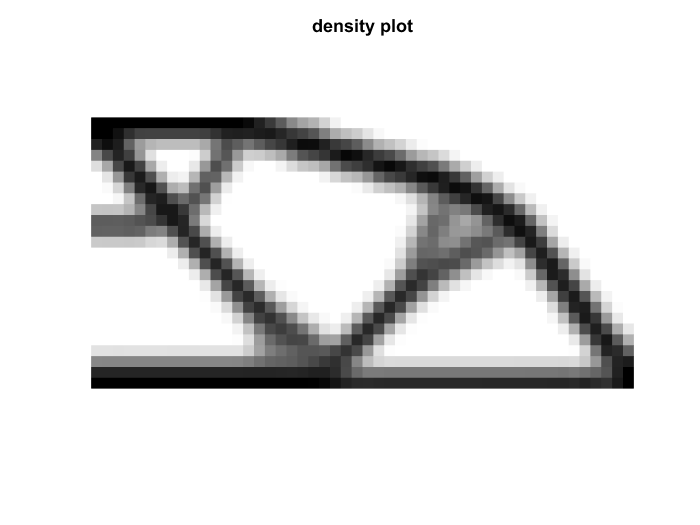

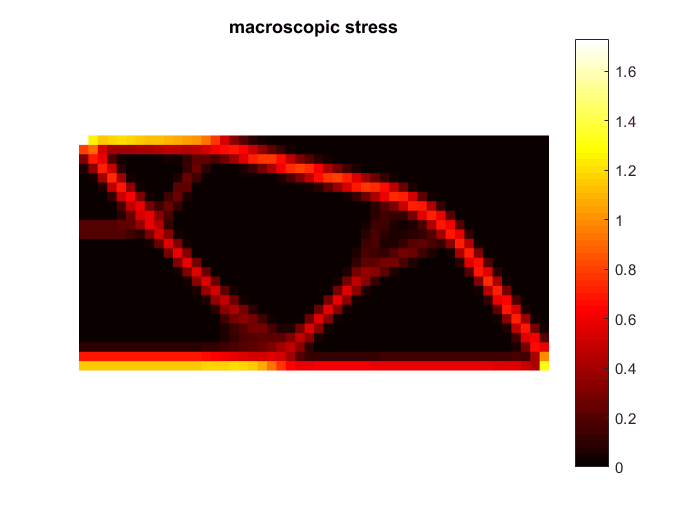

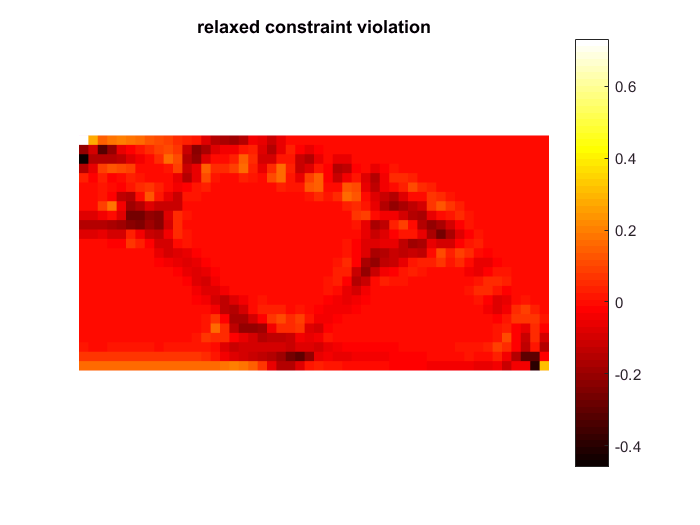

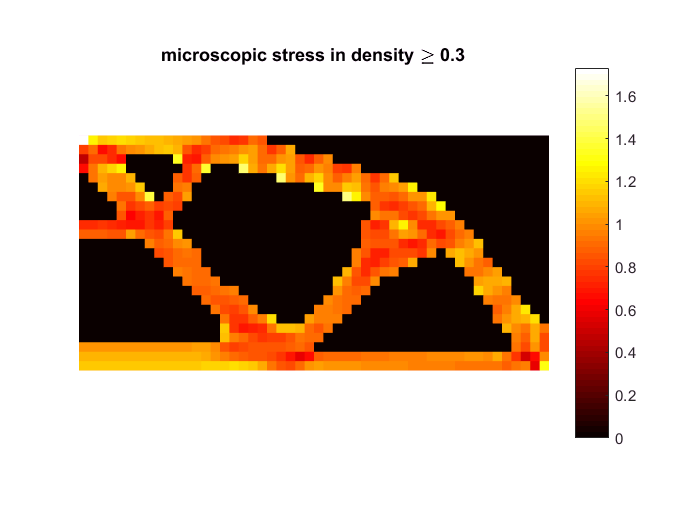

topstressMMA(50,25,3,2,2,1,4);

Still we can note that the constraint at the BC is violated due to the very small value of the aggregation parameter chosen in the unified approach.

On may also change the value of P in order to get feasible design.

Be aware that an increased value of P will also be the cause of a longer optimization time.

## References

[1] Verbart, Alexander, Matthijs Langelaar, and Fred Van Keulen. "A unified aggregation and relaxation approach for stress-constrained topology optimization." *Structural and Multidisciplinary Optimization* 55.2 (2017): 663-679.

[2] Coniglio, Simone, et al. "Original Pylon Architecture Design Using 3D HPC Topology Optimization." *2018 AIAA/ASCE/AHS/ASC Structures, Structural Dynamics, and Materials Conference*. 2018.

[3] Svanberg, K. (1987). The method of moving asymptotes—a new method for structural optimization. *International journal for numerical methods in engineering*, *24*(2), 359-373.

[4] Bendsøe, Martin P. "Optimal shape design as a material distribution problem." *Structural optimization* 1.4 (1989): 193-202.

[5] Zhou, M., and G. I. N. Rozvany. "The COC algorithm, Part II: topological, geometrical and generalized shape optimization." *Computer Methods in Applied Mechanics and Engineering* 89.1-3 (1991): 309-336.

[6] Duysinx, Pierre, and Martin P. Bendsøe. "Topology optimization of continuum structures with local stress constraints." *International journal for numerical methods in engineering* 43.8 (1998): 1453-1478.